This example illustrates how to create create a requirements set and organizes items under **F (Functional)**, **R (Requirements)**, **L (Logical)**, and **P (Physical)**.

The idea is to organize system requirements in a structured way:

- **Functional (F):** What the system must do.

- **Requirements (R):** Specific conditions under each function.

- **Logical (L):** Logical groupings of functionality.

- **Physical (P):** Physical allocations of system elements.

**NOTES: **

- Codes attached have seperate ".m" files, that can be ran seperately to get corresponding outputs.  

- All the desired functionalities cannot be achieved (easilyy) by just running codes, and would require some GUIs to help ease the process. Please make sure to go through both codes, and GUIs. 

## **Requirements Editor**

Add functional capabilities (F) and attach concrete requirements (R). Feel free to edit IDs/Summaries to your needs.

### Functional and Requirement Capabilities

#### **Code**

%% Requirements.m File. 
% Check if requirement set is already loaded
reqSet = slreq.find('Type','ReqSet','Name','F16A');

if isempty(reqSet)
    % Create a new requirement set if not loaded
    reqSet = slreq.new('F16A');

    % Add top-level requirement
    topReq = add(reqSet, 'Id', '1', 'Summary', 'F - Threat');

    % Add child requirements
    add(topReq, 'Id', '1.1', 'Summary', 'R - Detect');
    add(topReq, 'Id', '1.2', 'Summary', 'R - Target');
    add(topReq, 'Id', '1.3', 'Summary', 'R - Engage');
    add(topReq, 'Id', '1.4', 'Summary', 'R - Verify');

    % Add second branch
    req2 = add(reqSet, 'Id', '2', 'Summary', 'F - Structure/Loads');
    add(req2, 'Id', '2.1', 'Summary', 'R - Structure');

    % Add third branch
    req3 = add(reqSet, 'Id', '3', 'Summary', 'F - Propulsion');
    add(req3, 'Id', '3.1', 'Summary', 'R - Propulsion');

    % Save the requirement set
    save(reqSet, 'F16A.slreqx');
    disp('Requirement set F16A.slreqx created successfully.');
else
    disp('F16A.slreqx is already loaded. Skipping creation.');
end

F16A.slreqx is already loaded. Skipping creation.


**What the code does:**

- Checks if **F16A.slreqx** is already loaded (so you don’t duplicate it).

- Creates a **new requirements set** if it’s not loaded.

- Adds Functional requirements (F) with corresponding detailed Requirements (R).

- Add more **Functional/Requirement items** by duplicating the `add(...)` lines.

- Saves the requirements set as **F16A.slreqx**.

After running the script, open the **Requirements Editor** from the MATLAB Apps tab, or run:

% slreq.open

Click any requirement, and you will see fields for:

- **Description** (detailed text)

- **Rationale** (why this requirement exists)

- **Links** (traceability to models, tests, or documents)

This allows you to extend beyond the code structure and capture design intent.

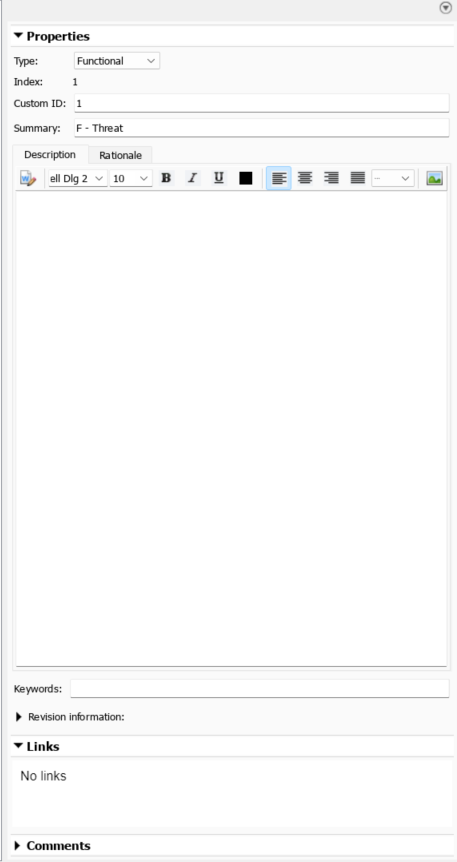

#### GUI

To create a new Requirement Set "F16-A.slreqx", click the *New Requirement Set* option using the **Requirements **Module in **Requirements Editor. **

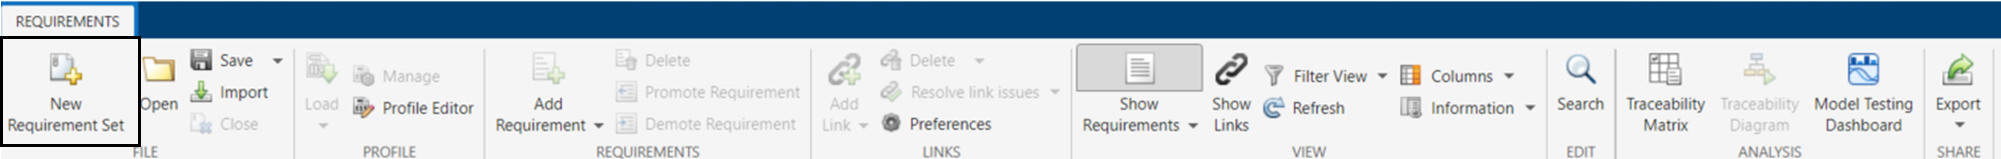

Any additional Requirements/Child Requirements can be created by clicking the *"Add Requirement" *option. A user can add a Child Requirement and a Requirement after the chosen Requirement.

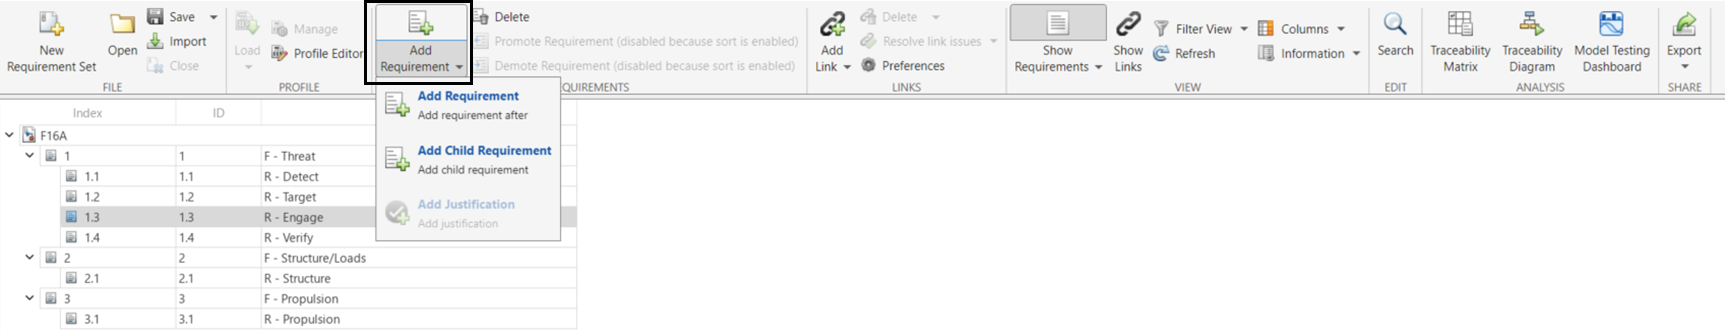

Furthermore, ensure to display the *"Implementation Status" *and *"Verification Status"* Options by **Right-Clicking **a requirement and going to *"Display". *

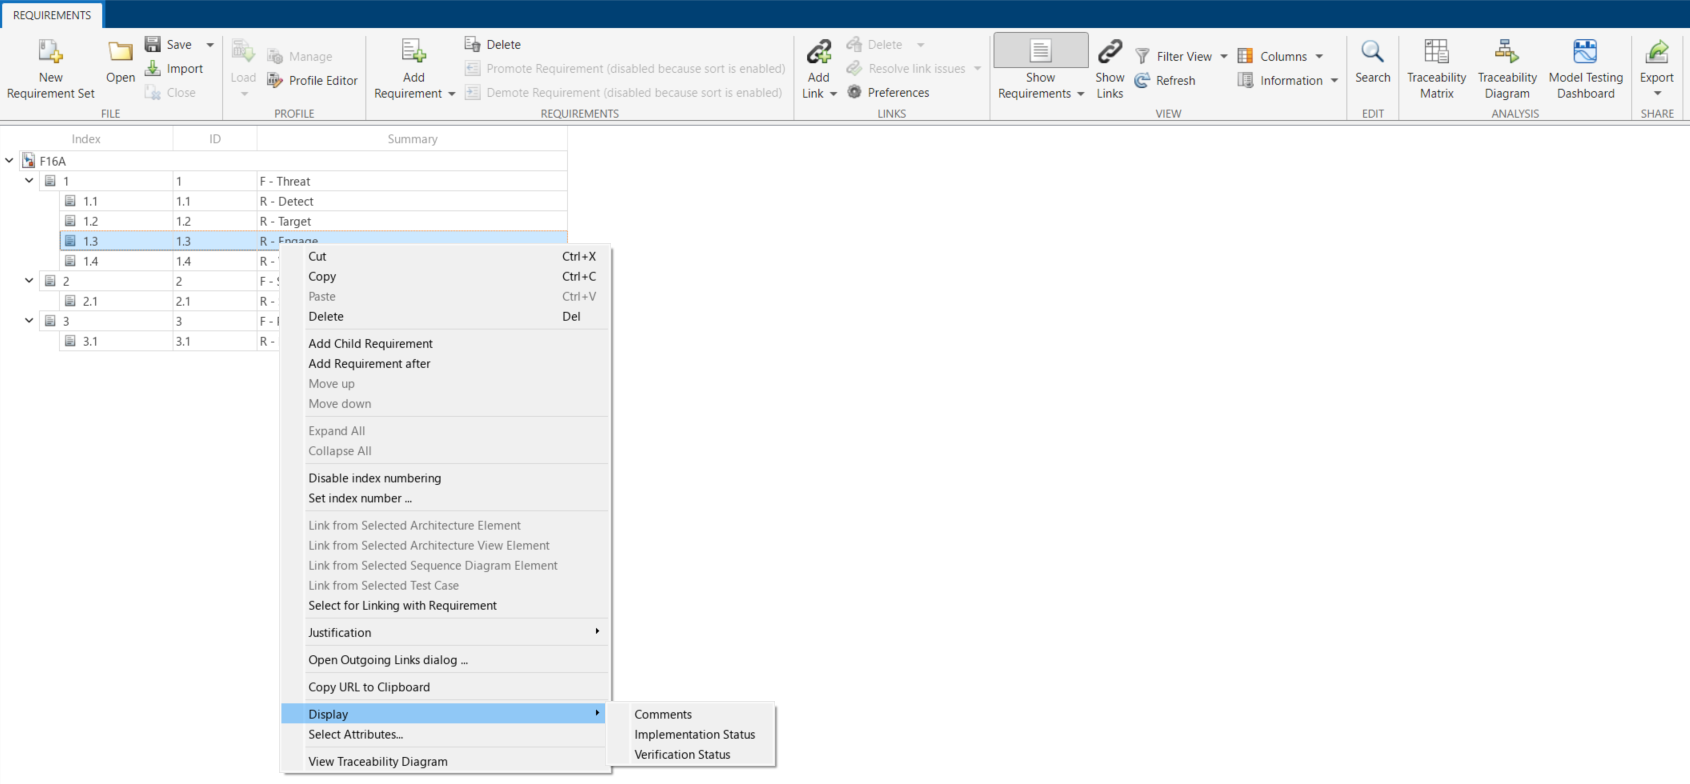

After clicking the options, the Implemented and Verified Options should like the below picture: 

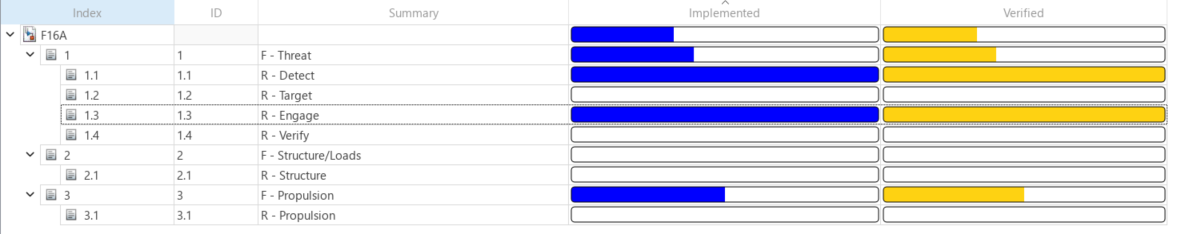

More on how to create a Requirements editor function through GUIs (Graphical User Interfaces) can be found here: [https://www.mathworks.com/help/slrequirements/ref/requirementseditor-app.html](https://www.mathworks.com/help/slrequirements/ref/requirementseditor-app.html)

## System Composer Module

Creating the Logical Options involves utilizing Matlab's System Composer Module. 

### Component Creation

#### Code

%% System Composer hierarchy: Aircraft -> (Wing, Fuselage) with subcomponents

modelName = 'Aircraft';

Not enough input arguments.

Error in slreq.open

% If a model with this name is already in memory, close it (no save)
if bdIsLoaded(modelName); close_system(modelName,0); end

% Create a new System Composer architecture model and open it
m    = systemcomposer.createModel(modelName);
systemcomposer.openModel(modelName);
% Handle to the root (top-level) architecture canvas
root = m.Architecture;

% Helper: place a component using Simulink's [Left Top Right Bottom] position.
% Input xywh = [left, top, width, height]; converts to [L T R B] and applies.
setCompPos = @(comp,xywh) set_param(comp.SimulinkHandle,'Position', ...
    [xywh(1) xywh(2) xywh(1)+xywh(3) xywh(2)+xywh(4)]);

%% Root components (top-level subsystems of the aircraft)
wing     = addComponent(root,'Wing');       % top-level Wing component
fuselage = addComponent(root,'Fuselage');   % top-level Fuselage component
% Place them so they don't overlap
setCompPos(wing,     [30  40 110 60]);
setCompPos(fuselage, [30 140 110 60]);

%% Wing -> Wingbox -> (nine_g, negative_three_g)
% Create Wingbox inside Wing
wingbox = addComponent(wing.Architecture,'Wingbox');
setCompPos(wingbox,[180 40 120 60]);

% Create two children inside Wingbox (e.g., load cases or structural items)
g1 = addComponent(wingbox.Architecture,'nine_g');
g2 = addComponent(wingbox.Architecture,'three_g');
% Place them under Wingbox
setCompPos(g1,[330 30 110 50]);
setCompPos(g2,[330 95 110 50]);

%% Fuselage -> Threat -> (Detect, Target, Engage, Verify)
% Create a Threat function inside Fuselage (will host functional children)
threat = addComponent(fuselage.Architecture,'Threat');
setCompPos(threat,[180 140 120 60]);

% Add four child functions under Threat
threatNames = {'Detect','Target','Engage','Verify'};
threatKids  = systemcomposer.arch.Component.empty;
% Layout parameters for horizontal spacing on the canvas
x0=330; dx=130; y0=140; w=120; h=60;

for i=1:numel(threatNames)
    % Add each child under the Threat component
    c = addComponent(threat.Architecture, threatNames{i});
    % Position each box with a fixed horizontal offset (dx)
    setCompPos(c,[x0+(i-1)*dx, y0, w, h]);
    threatKids(end+1) = c; % % collect handles for later use
end

% Grab a handle to the Detect component (first child) for further nesting
detect = threatKids(strcmp({threatKids.Name},'Detect'));

% Under Detect, add radar choices AESA and PESA
aesa = addComponent(detect.Architecture,'AESA');
pesa = addComponent(detect.Architecture,'PESA');
% Place AESA and PESA below the Detect box
setCompPos(aesa,[330 220 120 60]);
setCompPos(pesa,[460 220 120 60]);

**What the code will output**

- The model **Aircraft** is the top-level system.

- Inside it are **components** that stand for real subsystems: **Wing** and **Fuselage**.

- Components can be **decomposed** (drilled into).

- Double-click **Wing** → you see its internal part **Wingbox**.

- Double-click **Fuselage** → you’d add avionics/mission parts such as **Threat → Detect / Target / Engage / Verify**, and under **Detect** you might place **AESA** and **PESA** radars.

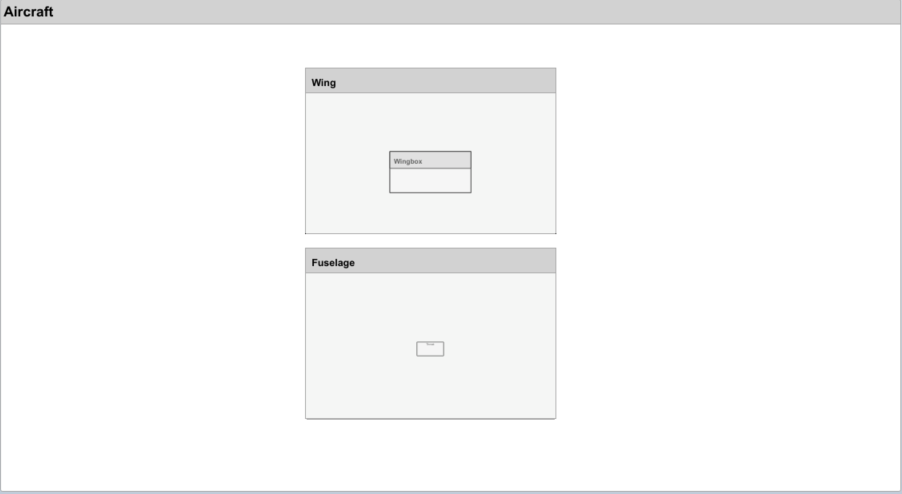

**Key ideas**

- **Architecture model**: a structured picture of the system—what parts exist and how they connect.

- **Component**: a box representing a physical or logical element (e.g., Wing, Fuselage, Radar).

- **Composition**: breaking a component into smaller components (hierarchy).

- **Ports & connectors**: where components exchange signals, power, fluids, etc.

- **Stereotypes (profiles)**: labels that add attributes (e.g., *Cost, Weight, Active*), and parameters (e.g., radar *Range, Power*) you can view/edit in the Property Inspector.

**How to interpret the hierarchy**

- **Top level (Aircraft)** shows major subsystems and their interfaces.

- **Wing** groups structural elements; **Wingbox** is one internal part.

- **Fuselage** groups mission systems; a **Threat** function can include **Detect/Target/Engage/Verify**, with sensor choices (**AESA/PESA**) under **Detect**.

- This **tree** lets you manage complexity: each box can be designed and verified separately, then integrated.

#### GUIs

The same components that were created with the above code can be created using the GUIs under the **"MODELING"** tab in the System Composer Module, by adding **Components**(Highlighted in Black). 

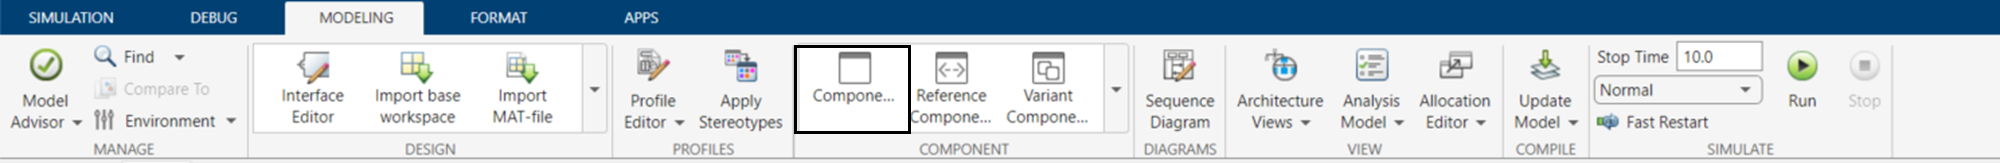

**Typical workflow using GUIs**

- **Create components** for the big parts (Wing, Fuselage, Propulsion…).

- **Decompose** each component into its internal parts (e.g., Wing → Wingbox), by double-clicking the component to go inside the component.

- Add **ports** to components and draw **connectors** to show interactions. This can be done by hovering over the edge of the component box. 

More information on System Composer can be found here: [https://www.mathworks.com/help/systemcomposer/ref/systemcomposer.arch.architecture.addcomponent.html](https://www.mathworks.com/help/systemcomposer/ref/systemcomposer.arch.architecture.addcomponent.html)

### Stereotypes and Parameters

**To have a better Idea of all the capabilities please look at "DetectProfile.xml" and import it into Profile Editor. **

Apply **stereotypes** (e.g., `Physical_Component`) so each part carries attributes like *Cost, Weight, Active*; add parameters where needed (e.g., for AESA/PESA components --> *Range, Power*). Using the GUIs are the easiest way to apply stereotypes and parameters.

Under the **"Modeling"** tab in System Composer, use the **"Profile Editor"** Option to Open/Import/Manage the Profiles in your path. 

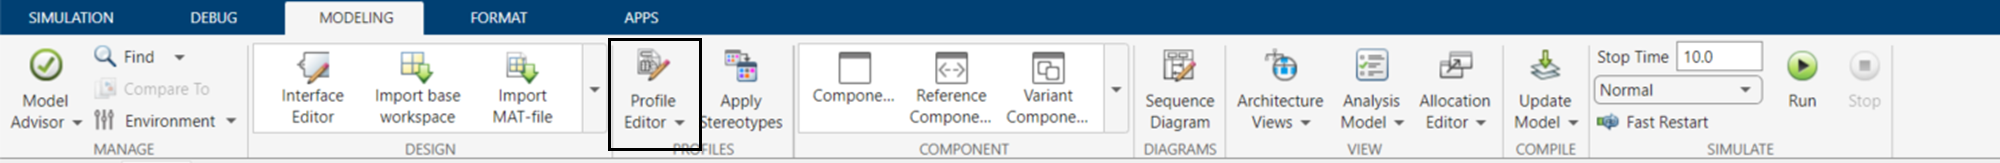

Use the **"New Profile"** option to create a new profile or use the **"Open"** option to open an exisitng profile. 

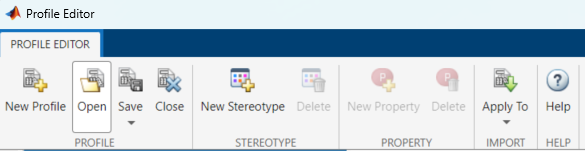

Add New Stereotypes using the **"New Stereotype"** option. Adding a "**Property***"* under the stereotype creates a particular attributes like Cost, Weight, and Active. One can also set the corresponding type as well. 

A stereotype can also be created for a component, port, and more, by clicking on the **"Applies to" **option. 

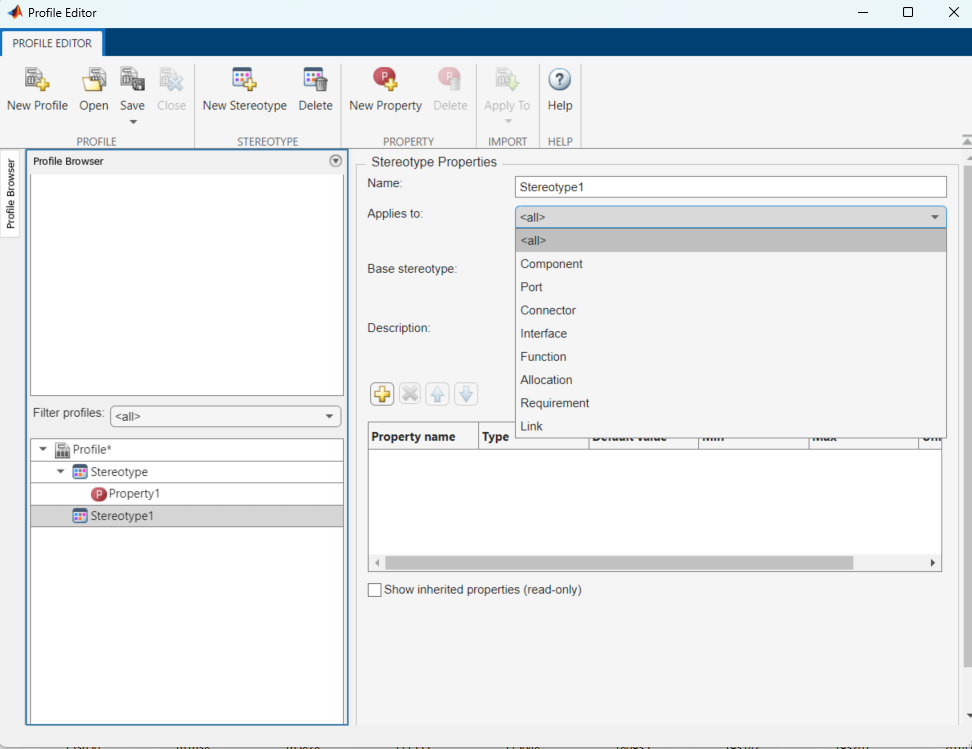

Furthermore, to ensure the stereotype that is created for the component is reflected in the created attribute (Cost, Weight, Active) the user has to click on the **"Base Stereotype"** and apply it to the stereotype that contains all the Attributes. 

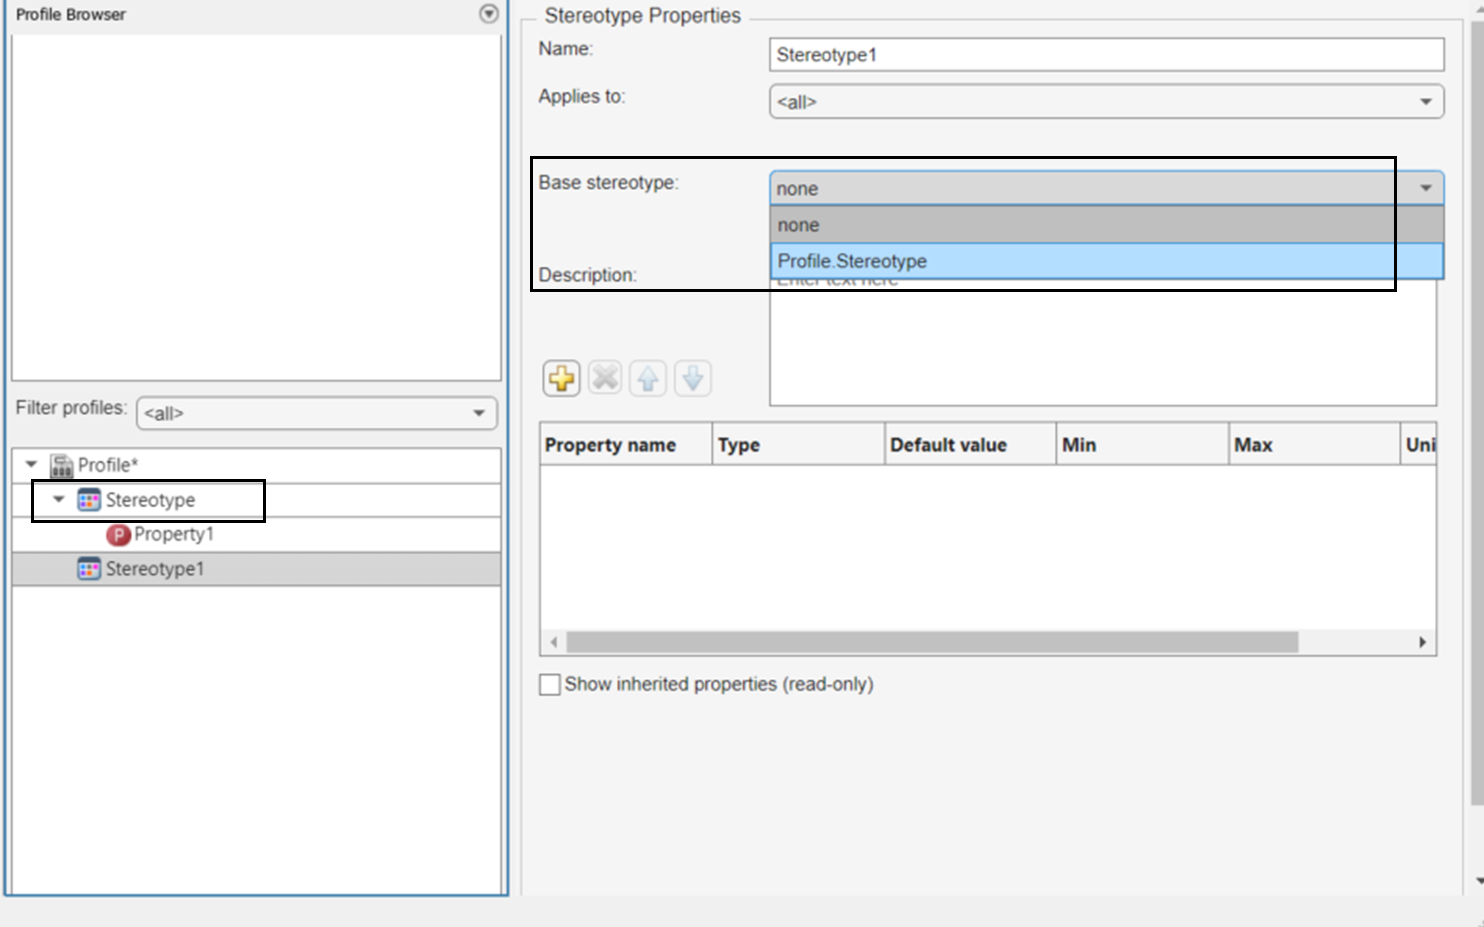

To make sure that the Profile applies to each and every component, Click on the **"Apply to"** button under the Profile Editor, and chose the correspnding .slx file. 

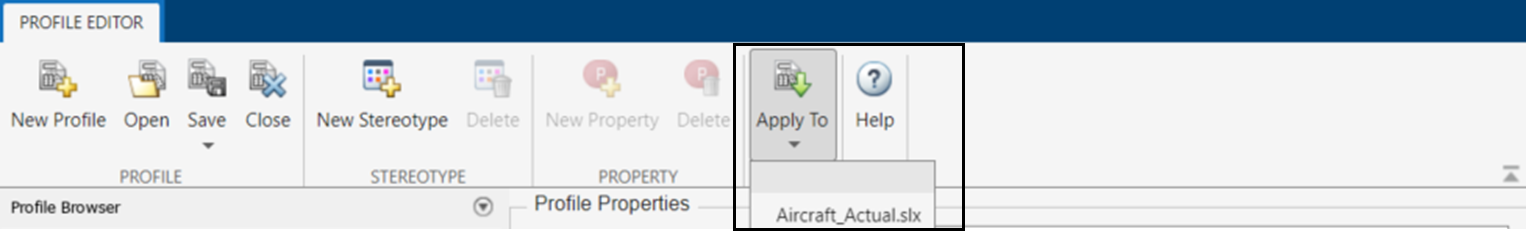

Use the "**Property Inspector"** to view/edit those values; set **defaults** in the profile so new parts are pre-filled. Access the Property Inspector by clicking on the arrow to the right of **Interface editor**. 

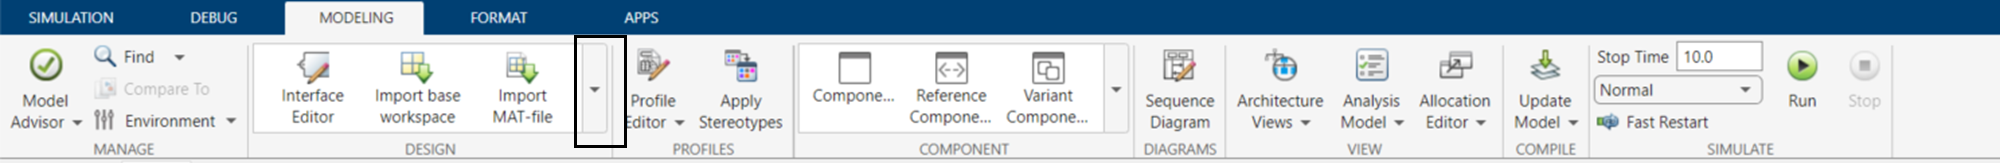

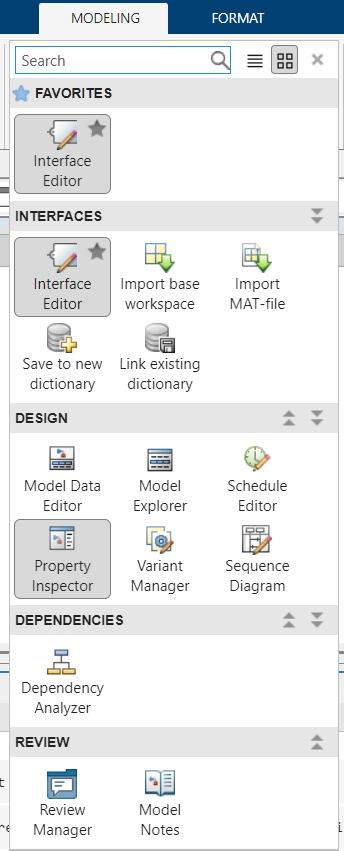

Clicking on the new Stereotype enables you to add the corresponding stereotype. Users can change the values in the box as well. Parameters can also be added for the corresponding component as well. 

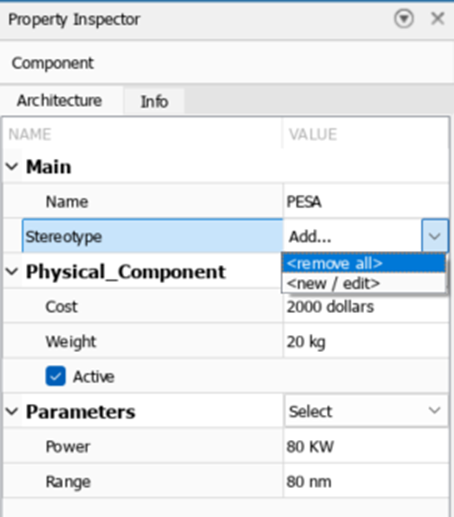

More information on Profile Editor can be found here: [https://www.mathworks.com/help/systemcomposer/ref/systemcomposer.profile.profile.createprofile.html](https://www.mathworks.com/help/systemcomposer/ref/systemcomposer.profile.profile.createprofile.html)

### Simulink Behavior

Right-Click on a particular Component and hover over **Create Behavior** and choose **Simulink Behavior** to ensure a particular System composer component has a simulink behavior. This is Another way to ensure that you can do the required analysis (for complicated Scenarios) in Simulink, rather than depending on stereotypes. 

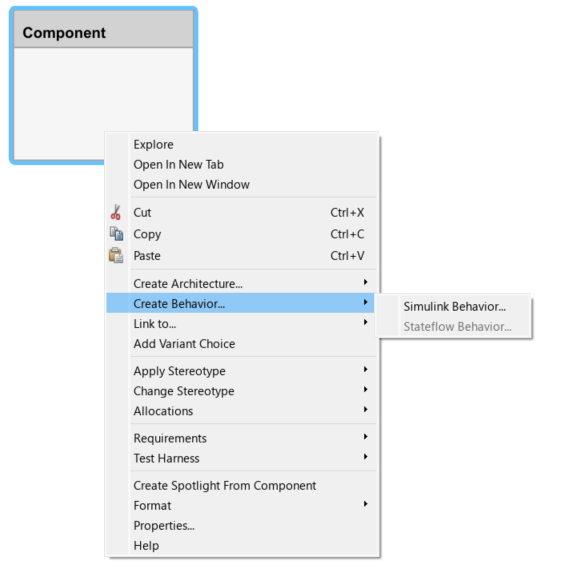

In the example provided, **nine_g.slx, and three_g.slx **are Simulink models/Components. (Wing--> Wingbox--> 9g and 3g).

More information on Simulink can be found here: 

[https://www.mathworks.com/help/simulink/index.html](https://www.mathworks.com/help/simulink/index.html)

## Linking Requirements

It is essential to **Link requirements** to components and run analyses or reports.

There are different ways to do this. Ensure to click the function/component to make sure that it is linked with the requirement. 

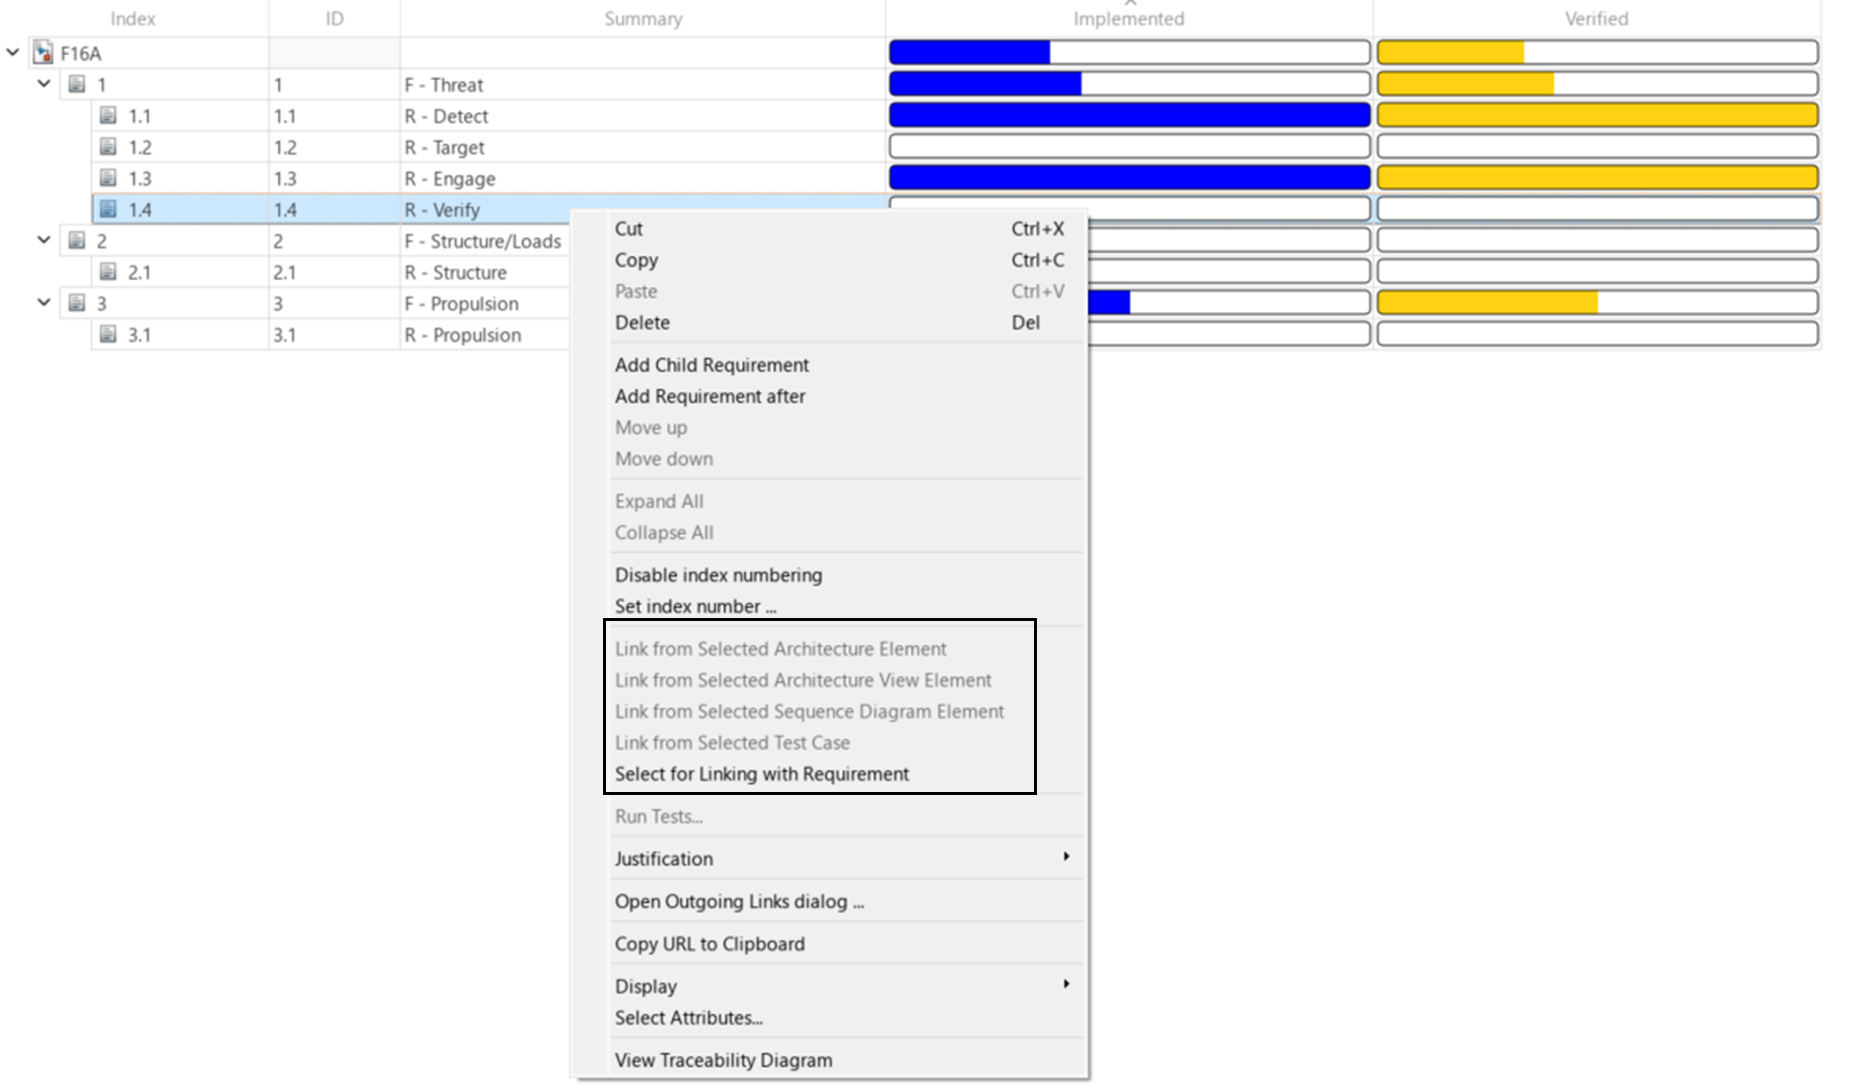

Use the **Traceability Matrix** to ensure the correct functionality (Verifies/Related to, etc. ) for each component. This can be viewed in the **Traceability Diagram.** 

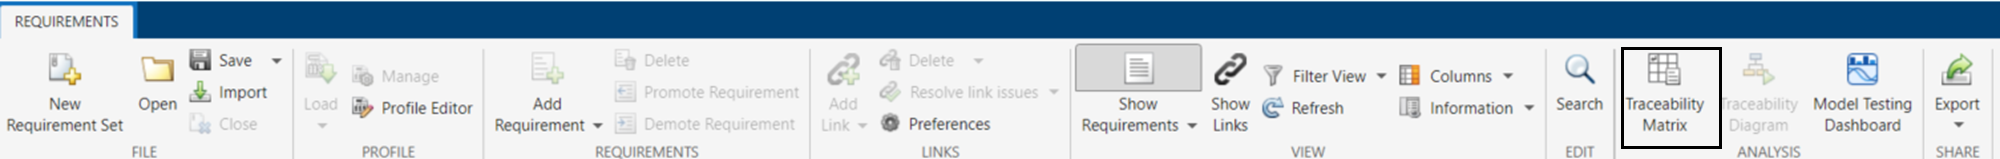

## Analyses

### **Detect requirement check (AESA vs PESA)**

We model two radars under **Detect** (AESA, PESA).

Each radar has:

- **Active** (TrialProfile → *Physical.Active*) — a checkbox indicating active sensing.

- **Range** (parameter, in **nm**) — detection range as a number in text form (e.g., `"120"`).

**Requirement:** If **Active = true**, then **Range > 100 nm** must hold.

If **Active = false**, the radar does not meet the “active” requirement (so the test will fail if we require Range > 100).

Where this lives in the architecture:

Path: `Aircraft/Fuselage/Threat/Detect` → children: **AESA**, **PESA**.

We’ll open the model, read each child’s **Active** and **Range**, and assert the rule.

This unit test opens the model, finds AESA/PESA under **Detect**, and checks:

- If **Active = "true"**, then **Range > 100**.

%%ActiveTest.m
classdef ActiveTest < matlab.unittest.TestCase
    % Define a test class that uses MATLAB’s unit test framework.
    % All tests in here must inherit from matlab.unittest.TestCase.
    methods (TestClassSetup)
        % Shared setup for the whole test class.
        % (Empty here — you could add code that runs once before all tests.)
    end

    methods (Test)
        % This block contains actual test methods.

        function verifyActive(testCase)
            % A test function that verifies whether "active" components
            % in the model have a Range greater than 100.

            % Open the System Composer model named "Aircraft.slx".
            model = systemcomposer.openModel("Aircraft"); 

            % Get the component object at the path "Aircraft/Fuselage/Threat/Detect".
            % This corresponds to the "Detect" block inside your architecture.          
            comp  = lookup(model, Path="Aircraft/Fuselage/Threat/Detect");   % get the component
            
            % Access the architecture definition of the "Detect" component.            
            arch = comp.Architecture;

            % Get all the child components of "Detect" (e.g., AESA, PESA).
            child = arch.Components;

            % Loop over each child component (like AESA, PESA).
            for k = 1:numel(child)

                % Get the name of the current child (a string like "AESA")
                indi = child(k).Name;

                % Uncomment to print the child’s name in the command window.
                %disp(child(k).Name)     

                % Look up the full path to the current child component inside the model.
                updated_comp = lookup(model, Path="Aircraft/Fuselage/Threat/Detect/" + indi);

                % Save the full path as text (for display or debugging).
                childPath="Aircraft/Fuselage/Threat/Detect/" + indi;
                
                % Read the stereotype property "Active" from the child.
                % This tells you if the radar (AESA/PESA) is marked as active.
                active_stereo = updated_comp.getPropertyValue('DetectProfile.Physical.Active'); 
                
                % Get the Simulink parameter object called "Range" from the child.
                range_stereo = updated_comp.getParameter("Range");                  % parameter object
                
                % Convert the Range parameter’s stored string into a numeric value.
                % (sscanf reads the number out of the text string.)
                range_stereo_val   = sscanf(range_stereo.Value, '%f', 1);  % read
                
                % Print the numeric range value to the command window.
                disp(range_stereo_val); 

                % If the child’s Active property is set to "true"
                if active_stereo == "true"

                    % Print the full path of the active component (for context).
                    disp(childPath)

                    % Test assertion: check that the range is greater than 100.
                    % If not, the test fails.
                    testCase.verifyGreaterThan(range_stereo_val, 100);
                end
            end              
        end
    end
end

This is linked to the **Requirement - Detect**

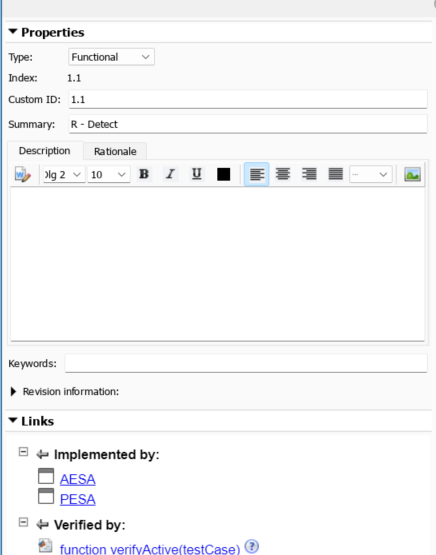

**NOTES:**

- **Active** is a **stereotype property** (from your profile), shown in the Property Inspector when the component is selected.

- **Range** is a **component parameter** (string value). We parse it to a number for comparison.

- The test ties **architecture data** (Active/Range) to a clear **requirement** (Range > 100 when Active).

- To explore, toggle **Active** and adjust **Range**, then re-run the test to see pass/fail.

### **Structural Integrity Test**

Here’s what the test does, at a high level:

- Opens the **Aircraft** architecture and goes to **Wing → Wingbox → Load**.

- For each load case under **Load** (e.g., **nine_g**, **three_g**), it loads the referenced Simulink model.

- Temporarily disables any Scope blocks (so no GUIs pop up), runs a simulation, and captures the numeric outputs.

- Checks that the **final output equals 1** for each load case (interpreted as “pass”).

- Restores any blocks it disabled and reports overall **pass/fail** results via MATLAB’s unit test framework.

%%Test_structural_integrity.m
classdef Test_structural_integrity < matlab.unittest.TestCase

Illegal use of reserved keyword "classdef".

    % A unit test class that checks outputs of the Load components
    % (nine_g, three_g) inside the Aircraft model.

    methods (TestClassSetup)
        % Runs once before all tests in this class.
        % Right now it’s empty, but you could open the model here.
    end

    methods (Test)
        function verify_Structural_Test(testCase)
            % A test that loops through each child of the Load component
            % and verifies its final simulation output.

            % --- Open the top-level System Composer model
            model = systemcomposer.openModel("Aircraft");

            % --- Look up the "Load" component inside the model
            comp  = lookup(model, Path="Aircraft/Wing/Wingbox/Load");

            % --- Get its architecture and all child components
            arch  = comp.Architecture;
            child = arch.Components;

            % --- Loop over each child (e.g., nine_g, three_g)
            for k = 1:numel(child)
                indi = child(k).Name;    % Get the child’s name
                %disp(class(indi))        % Show the datatype of the name

                % --- Look up the full child component object
                updated_comp = lookup(model, Path="Aircraft/Wing/Wingbox/Load/" + indi);

                % --- Get Simulink block handle and referenced model name
                blkH   = updated_comp.SimulinkHandle;    % Handle to the Simulink block
                mdlRef = get_param(blkH, "ModelName");   % Name of referenced model (e.g., 'nine_g')
                disp(mdlRef)

                % --- Convert to char (some Simulink APIs don’t accept string)
                mdlRef_c = char(mdlRef);

                % --- Load the referenced model so it’s ready to simulate
                load_system(mdlRef_c);

                % --- Find Scope and Time Scope blocks in the model
                scopeBlks = [ ...
                    find_system(mdlRef_c,'LookUnderMasks','all','FollowLinks','on','BlockType','Scope'); ...
                    find_system(mdlRef_c,'LookUnderMasks','all','FollowLinks','on','Regexp','on','MaskType','Time Scope') ];
                scopeBlks = cellfun(@char, scopeBlks, 'UniformOutput', false);  % Ensure char format

                % --- Comment out all scopes to avoid GUI errors in tests
                origComment = cell(size(scopeBlks));
                for i = 1:numel(scopeBlks)
                    if isempty(scopeBlks{i}), continue; end
                    origComment{i} = get_param(scopeBlks{i}, 'Commented');  % Save original state
                    set_param(scopeBlks{i}, 'OpenAtSimulationStart','off'); % Prevent auto-opening
                    set_param(scopeBlks{i}, 'Commented','on');              % Comment (disable) block
                end

                try
                    % --- Prepare simulation input object for the model
                    in = Simulink.SimulationInput(mdlRef_c);
                    % --- If you don't save it as an array --> default is
                    % timeseries and it would check the condition each
                    % time. 
                    in = in.setModelParameter('ReturnWorkspaceOutputs','on', ...
                                              'SaveOutput','on', ...
                                              'OutputSaveName','yout', ...
                                              'SaveFormat','Array');

                    % --- Run the simulation
                    out   = sim(in);

                    % --- Get outputs: numeric array from root Outports
                    yout  = out.yout;
                    final = yout(end,:);   % Take the last row (final time sample)

                    disp(final)            % Print the final value

                    % --- Verify that the final output equals 1
                    testCase.verifyEqual(final,1);

                catch ME
                    % --- On error: restore scopes, then rethrow error
                    for i = 1:numel(scopeBlks)
                        if isempty(scopeBlks{i}), continue; end
                        set_param(scopeBlks{i}, 'Commented', origComment{i});
                    end
                    rethrow(ME)
                end

                % --- After success: restore scopes back to original state
                for i = 1:numel(scopeBlks)
                    if isempty(scopeBlks{i}), continue; end
                    set_param(scopeBlks{i}, 'Commented', origComment{i});
                end
            end  % end for-loop
        end      % end test function
    end          % end methods (Test)
end              % end classdef

To run the linked Tests from Requirements Editor, one can right click on the Overall Requirement and select **Run Tests**: 

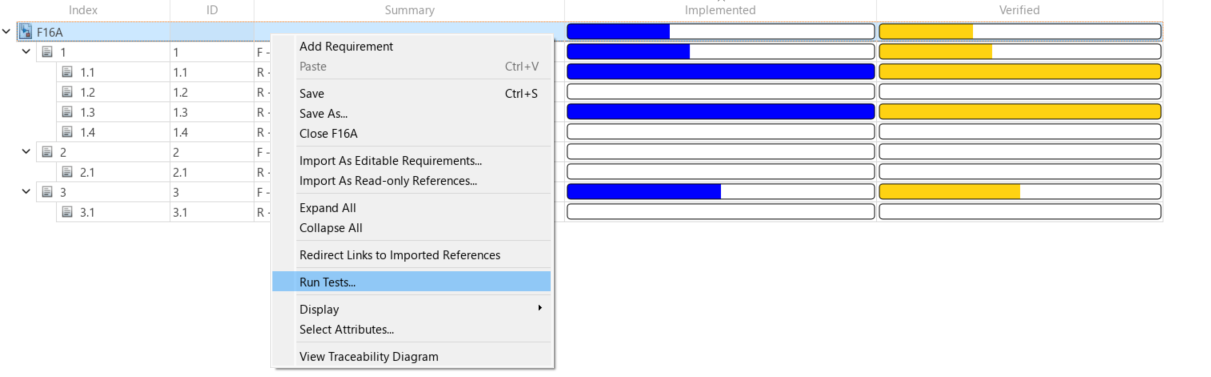

This will run all the tests together. individually, one can run a particular requirement's test as well, by following the same procedure. 

### **Roll-up Analysis**

Example: [https://www.mathworks.com/help/systemcomposer/ug/simple-roll-up-analysis.html](https://www.mathworks.com/help/systemcomposer/ug/simple-roll-up-analysis.html)

Simple roll-up analysis to calculate the total weight and cost of the system from its individual parts. 

#### Code

High-level idea:

- **Creates an instance model** of `Aircraft` (a snapshot of the architecture for analysis) using your profile.

- **Runs a post-order “roll-up” analysis** (`CostAndWeightRollupAnalysis`) over every instance element—children first, then parents—so each parent’s **Cost** and **Weight** are computed from its children.

- **Enforces constraints** during instantiation (`Strict=true`) and keeps original units (`NormalizeUnits=false`).

- **Reads the aggregated totals** from the **root instance** (`Aircraft`) via the profile properties (e.g., `*.Physical.Cost`, `*.Physical.Weight`).

- **Displays** the aircraft-level rolled-up **Cost** and **Weight**.

In short: it instantiates the architecture, walks the hierarchy, **accumulates Cost/Weight up the tree**, and then reports the **top-level totals**.

%%Model_Instance.m
function model_instance()
    % Open the System Composer architecture model.
    model = systemcomposer.openModel("Aircraft");        

    % Create an instance model from the architecture using a profile.
    % - "DetectProfile" must match the profile applied to your components.
    % - "NewInstance" is the name of the created instance model.
    % - Function: analysis callback run during instantiation on each element.
    % - Strict=true: enforce profile constraints during instantiation.
    % - NormalizeUnits=false: keep original units (no normalization).
    % - Direction="Postorder": visit children before parents.
    modelInstance = instantiate( ...
        model.Architecture, ...          % source architecture
        "DetectProfile", ...             % profile name used by the model
        "NewInstance", ...               % instance model name
        Function=@CostAndWeightRollupAnalysis, ...
        Strict=true, ...
        NormalizeUnits=false, ...
        Direction="Postorder");

    % Walk the instance model (again in postorder) and run the same analysis
    % function over every instance element (recurse into hierarchy).
    iterate(modelInstance, "Postorder", @CostAndWeightRollupAnalysis, Recurse=true);

    % Grab the root instance component of the instantiated model.
    root = lookup(modelInstance, 'Path', 'Aircraft');

    % Read rolled-up property values (as computed/attached by the analysis)
    % from the instance: total Cost and Weight stored on the Physical stereotype.
    cost_aircraft   = root.getValue('DetectProfile.Physical.Cost');
    weight_aircraft = root.getValue('DetectProfile.Physical.Weight');

    % Display aggregated Cost and Weight for the whole aircraft instance.
    disp(cost_aircraft)
    disp(weight_aircraft)
end

The CostandWeightRollupAnalysis.m file, **High-level overview (roll-up analysis):**

- Walks the **instance hierarchy bottom-up** (children first, then parent).

- For **each component**:

- Reads the `DetectProfile.Physical.Active` flag.

- If **Active = true**, takes that node’s `Cost` and `Weight` (converts strings to numbers).

- Recursively **adds children’s totals** to the parent.

- Writes the **rolled-up Cost and Weight back onto every node**, so each component shows its own + all descendants’ totals.

- **Inactive components contribute 0** (they’re skipped), so only **active** parts affect the aggregate.

function CostAndWeightRollupAnalysis(instance, varargin)
    if ~instance.isComponent(); return; end
    rollupAndSet(instance);   % recurse bottom-up

    function [cSum, wSum] = rollupAndSet(node)
        % Active flag (handles string/char/logical)
        isActive = false;
        if node.hasValue('DetectProfile.Physical.Active')
            v = node.getValue('DetectProfile.Physical.Active');
            if isstring(v) || ischar(v)
                isActive = strcmpi(string(v),"true");
            else
                isActive = logical(v);
            end
        end

        % this node's own contribution (only if Active)
        cSum = 0;  wSum = 0;
        if isActive
            if node.hasValue('DetectProfile.Physical.Cost')
                cSum = cSum + double(node.getValue('DetectProfile.Physical.Cost'));
            end
            if node.hasValue('DetectProfile.Physical.Weight')
                wSum = wSum + double(node.getValue('DetectProfile.Physical.Weight'));
            end
        end

        % add children recursively
        for ch = node.Components
            [cc, ww] = rollupAndSet(ch);
            cSum = cSum + cc;  wSum = wSum + ww;
        end

        % write totals so Analysis Viewer shows roll-up at every level
        if node.hasValue('DetectProfile.Physical.Cost')
            node.setValue('DetectProfile.Physical.Cost', cSum);
        end
        if node.hasValue('DetectProfile.Physical.Weight')
            node.setValue('DetectProfile.Physical.Weight', wSum);
        end
    end
end

#### GUIs

Use the **Analysis Model **on the **Modeling Tab **in **System Composer**, to perform Roll-up-Analysis. 

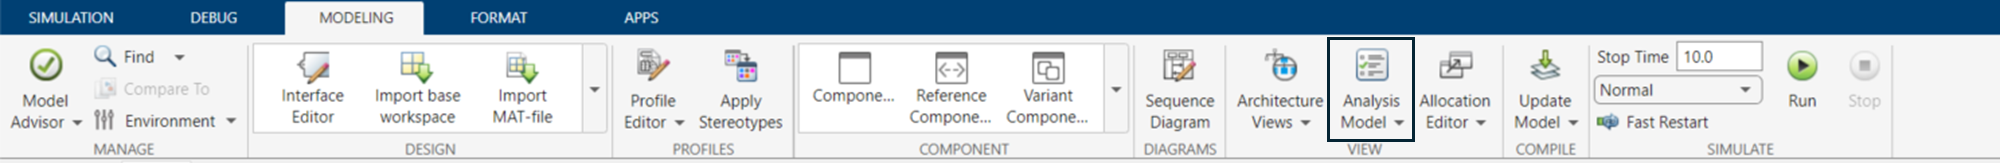

Select the Stereotype, Analysis Function(CostandWeightRollupAnalysis.m) and select the Iteration Order as well. Then click Instanitate. 

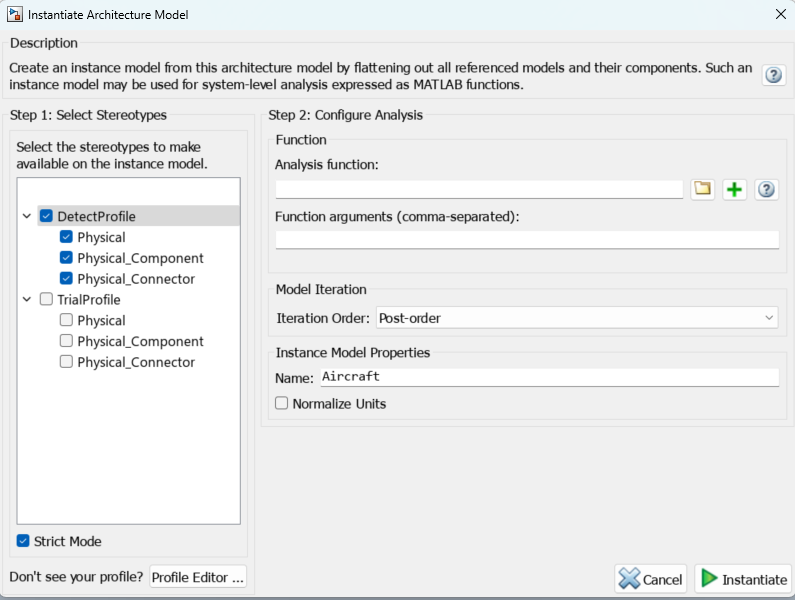

More on the Analysis Tool can be found here: [https://www.mathworks.com/help/systemcomposer/ug/analyze-architecture.html](https://www.mathworks.com/help/systemcomposer/ug/analyze-architecture.html)